# UV LED Pulse Family for UP and DOWN ON DSGCs

Intensity response functions

Cells here were recorded in cell attached mode on the patch rig. Looking at spikes only

% downs = grabFromFilter('Downs', 'ExcludeSingleLabels');
% ups = grabFromFilter('Ups', 'ExcludeSingleLabels');

ups = grabFromFilter('UP Cells');
downs = grabFromFilter('DOWN Cells');

windowTime = 25; %ms
%choose which protocols to look at
priorityOrder_1 = {'LedPulseFamily'}; %first field name should be one of these. Priority is in given order
priorityOrder_2 = {'_UV_ff'}; %child field name should be one of these. Priority is in given order
priorityOrder_1b = {'Flash'};
priorityOrder_2b = {'_ff'; '_all'};
mustHave_1 = [];
mustHave_2 = {'Extracellular'};
cantHave_1 = [];
cantHave_2 = {'Cesium', 'Intracellular', 'Potassium'}; %avoid anything with these tags
rigMandates = [{'LEDSpotDiameter'}, {500}]; %use only cells with LED spot diameter = 500

up_Ionehalfs = [];
upNames = {};
upPSTH = [];
upFitParams = [];
for i = 1:size(ups, 1)
    struct_i = ups{i, 2};
 
    [loc, pass] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2, cantHave_2, rigMandates);
    
    if pass
        continue
    end
    [loc_b, ~] = getLoc(struct_i, priorityOrder_1b, mustHave_1, cantHave_1, priorityOrder_2b, mustHave_2, cantHave_2, rigMandates);
    
    
    preTime_i = loc_b.meta.preTime;
    stimTime_i = loc_b.meta.stimTime;
    tailTime_i = loc_b.meta.tailTime;
    
    totalTime = preTime_i + stimTime_i + tailTime_i;
    
    if totalTime ~= 3000
        continue
    end
    spikeTimes_i = loc_b.Analysis_Results.allSpikeTimes;
    
    numBins = numel(0:windowTime:(totalTime-windowTime));
    results_i = zeros(numel(spikeTimes_i), numBins);
    
    %average across all epochs
    for j = 1:numel(spikeTimes_i)
        s = spikeTimes_i{j};
        psth_j = zeros(1, numBins);
        for k = 0:numBins-1
            spikesInWindow = numel(s(s>k*windowTime & s<(k*windowTime+windowTime)))/(windowTime/1000);
            psth_j(k+1) = spikesInWindow;
        end
        results_i(j, :) = psth_j;
    end
    
    if j == 1
        meanResults = results_i;
    else
        meanResults = mean(results_i);
    end
    upPSTH = [upPSTH; meanResults];
    
    up_Ionehalfs = [up_Ionehalfs, loc.Analysis_Results.MConeHillFit.I_OneHalf];
    mfit= loc.Analysis_Results.MConeHillFit;
    upFitParams = [upFitParams; mfit.I_OneHalf, mfit.exponent, mfit.minimum, mfit.maximum];
    upNames{end+1} = ups{i, 1};
end

down_Ionehalfs = [];
downNames = {};
downPSTH = [];
downFitParams = [];
for i = 1:size(downs, 1)
    struct_i = downs{i, 2};
    
    [loc, pass] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2, cantHave_2, rigMandates);
    
    if pass
        continue
    end
    [loc_b, ~] = getLoc(struct_i, priorityOrder_1b, mustHave_1, cantHave_1, priorityOrder_2b, mustHave_2, cantHave_2, rigMandates);
        
    preTime_i = loc_b.meta.preTime;
    stimTime_i = loc_b.meta.stimTime;
    tailTime_i = loc_b.meta.tailTime;
    
    totalTime = preTime_i + stimTime_i + tailTime_i;
    
    if totalTime ~= 3000
        continue
    end
    spikeTimes_i = loc_b.Analysis_Results.allSpikeTimes;
    
    numBins = numel(0:windowTime:(totalTime-windowTime));
    results_i = zeros(numel(spikeTimes_i), numBins);
    
    %average across all epochs
    for j = 1:numel(spikeTimes_i)
        s = spikeTimes_i{j};
        psth_j = zeros(1, numBins);
        for k = 0:numBins-1
            spikesInWindow = numel(s(s>k*windowTime & s<(k*windowTime+windowTime)))/(windowTime/1000);
            psth_j(k+1) = spikesInWindow;
        end
        results_i(j, :) = psth_j;
    end
    
    if j == 1
        meanResults = results_i;
    else
        meanResults = mean(results_i);
    end
    downPSTH = [downPSTH; meanResults];
    
    down_Ionehalfs = [down_Ionehalfs, loc.Analysis_Results.MConeHillFit.I_OneHalf];
    mfit= loc.Analysis_Results.MConeHillFit;
    downFitParams = [downFitParams; mfit.I_OneHalf, mfit.exponent, mfit.minimum, mfit.maximum];
    downNames{end+1} = downs{i, 1};
end



## All Hill fits

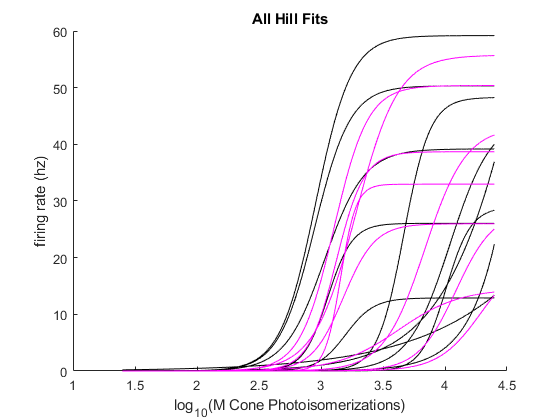

%showing M cone hill fits for every cell
xvals = linspace(0, 25000, 1000);
hill = @(b, x) ((b(3) + (b(4) - b(3))) ./ (1 + (b(1) ./ x).^b(2)));  % Function to fit
figure
title('All Hill Fits')
hold on
for c = 1:size(upFitParams, 1)
    b = upFitParams(c, :)';
    fitValues = hill(b, xvals);
    plot(log10(xvals), fitValues, '-k')
end

for c = 1:size(downFitParams, 1)
    b = downFitParams(c, :)';
    fitValues = hill(b, xvals);
    plot(log10(xvals), fitValues, '-m')
end
xlabel('log_1_0(M Cone Photoisomerizations)')
ylabel('firing rate (hz)')

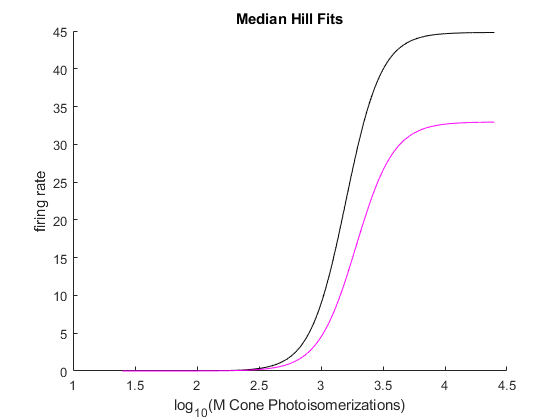

% mean fits
medianUpParams = median(upFitParams([1,4:end], :))';
medianDownParams = median(downFitParams)';
upFitVals = hill(medianUpParams, xvals);
downFitVals = hill(medianDownParams, xvals);

figure
title('Median Hill Fits')
hold on
plot(log10(xvals), upFitVals, '-k', log10(xvals), downFitVals, '-m')
xlabel('log_1_0(M Cone Photoisomerizations)')
ylabel('firing rate')

## I 1/2

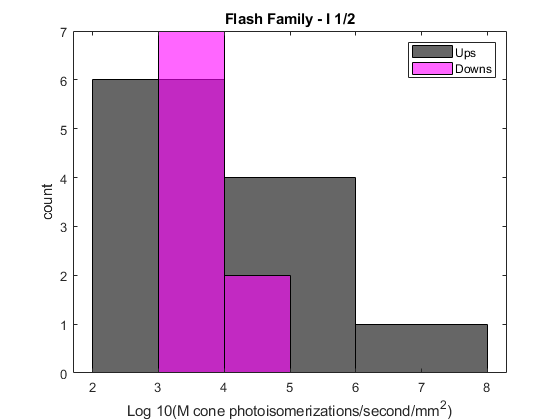


figure
histogram(log10(up_Ionehalfs), 'FaceColor', 'black')
hold on
histogram(log10(down_Ionehalfs), 'FaceColor', 'magenta', 'FaceAlpha', 0.6)
title('Flash Family - I 1/2')
xlabel('Log 10(M cone photoisomerizations/second/mm^2)')
ylabel('count')
legend('Ups', 'Downs')


ranksum(up_Ionehalfs, down_Ionehalfs)

ans = 0.9394


up_maxFiringRates = max(upPSTH, [], 2);
down_maxFiringRates = max(downPSTH, [], 2);

ranksum(up_maxFiringRates, down_maxFiringRates)

ans = 0.0474

## Max firing rate vs. log(I one half)


% upFirst100ms = upPSTH(:, xvals>1000 & xvals < 1100);
% downFirst100ms = downPSTH(:, xvals>1000 & xvals<1100);
% maxUpFirst100ms = max(upFirst100ms, [], 2);
% maxDownFirst100ms = max(downFirst100ms, [],2);
% 
% ranksum(maxUpFirst100ms, maxDownFirst100ms)

% linear correlation coefficients for max firing rate vs log i one half
[upR, upRP] = corrcoef(up_maxFiringRates, log10(up_Ionehalfs))

upR =     1.0000   -0.7463
   -0.7463    1.0000


upRP =     1.0000    0.0083
    0.0083    1.0000


[downR, downRP] = corrcoef(down_maxFiringRates, log10(down_Ionehalfs))

downR =     1.0000   -0.7800
   -0.7800    1.0000


downRP =     1.0000    0.0132
    0.0132    1.0000



up_Slope = upR(2) * std(log10(up_Ionehalfs))/std(up_maxFiringRates);
up_Intercept = mean(log10(up_Ionehalfs)) - up_Slope*mean(up_maxFiringRates);

down_Slope = downR(2) * std(log10(down_Ionehalfs))/std(down_maxFiringRates);
down_Intercept = mean(log10(down_Ionehalfs)) - down_Slope*mean(down_maxFiringRates);

xvals = linspace(min([up_maxFiringRates', down_maxFiringRates']),...
    max([up_maxFiringRates', down_maxFiringRates']));
up_yVals = up_Slope * xvals + up_Intercept;
down_yVals = down_Slope * xvals + down_Intercept;


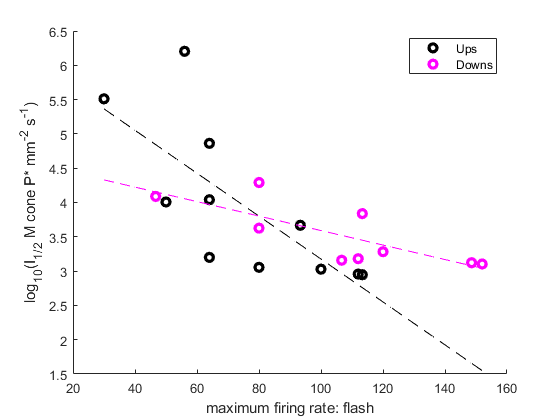

figure
scatter(up_maxFiringRates, log10(up_Ionehalfs), 'k', 'LineWidth',2.5)
hold on
scatter(down_maxFiringRates, log10(down_Ionehalfs), 'm', 'LineWidth', 2.5)
plot(xvals, up_yVals, '--k', xvals, down_yVals, '--m')
xlabel('maximum firing rate: flash')
ylabel('log_1_0(I_1_/_2 M cone P* mm^-^2 s^-^1)')
lgd = legend('Ups', 'Downs');
lgd.Location = 'best';